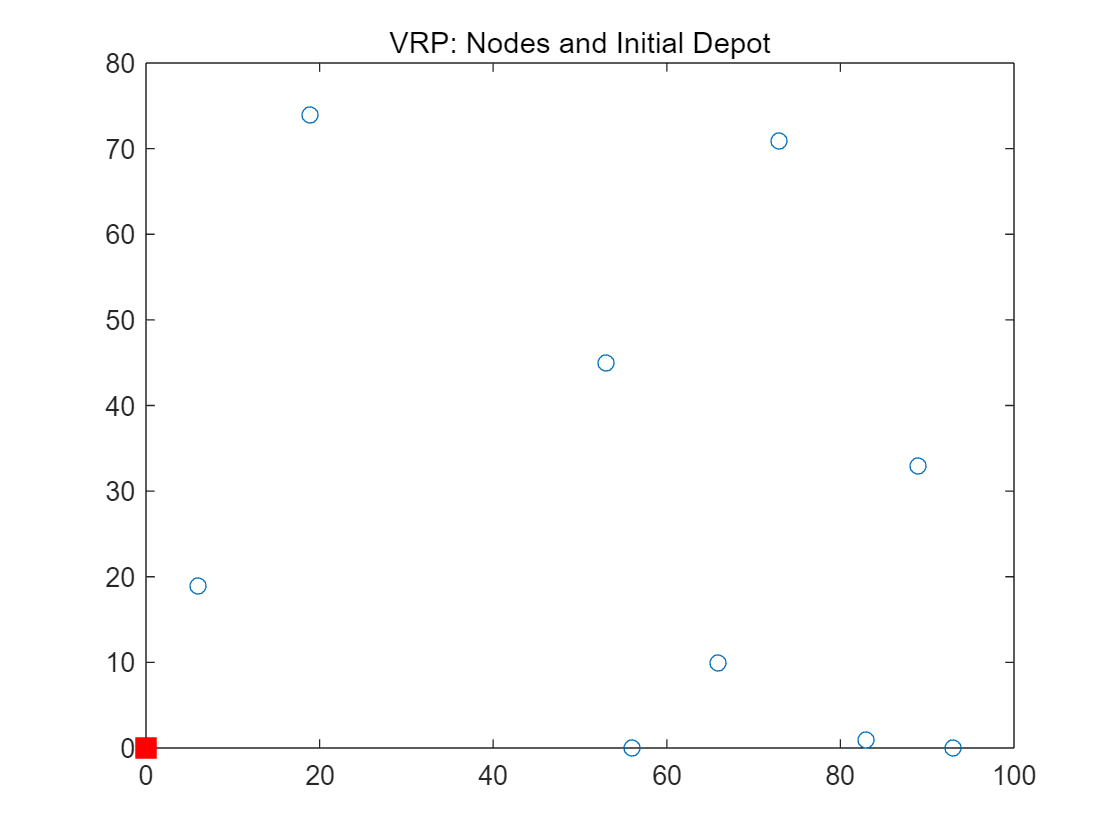

% 主脚本部分

% Number of nodes (including the depot)
n = 10;

% Coordinates of the nodes (including the depot at (0, 0))
x = randi([0, 100], n, 1);
y = randi([0, 100], n, 1);
x(1) = 0;
y(1) = 0;

% Plot the nodes
figure;
plot(x, y, 'o');
hold on;
plot(x(1), y(1), 'rs', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Depot
title('VRP: Nodes and Initial Depot');


% Distance matrix
dist = zeros(n, n);
for i = 1:n
    for j = 1:n
        dist(i, j) = sqrt((x(i) - x(j))^2 + (y(i) - y(j))^2);
    end
end

% Solve VRP using Genetic Algorithm
options = optimoptions('ga', 'PlotFcn', {@gaplotbestf, @gaplotstopping});
[route, total_dist] = ga(@(route) calculate_distance(route, dist), n, [], [], [], [], ones(1, n), n*ones(1, n), @(route) vrp_constraints(route, n), options);

Optimization finished: MaxStallGenerations exceeded but constraints are not satisfied within options.ConstraintTolerance.


route

route =     8.1230    9.2075    5.9866    4.4008    6.6856    9.9696    3.0786    7.7806    4.9041    2.2887


total_dist

total_dist = 352.6960

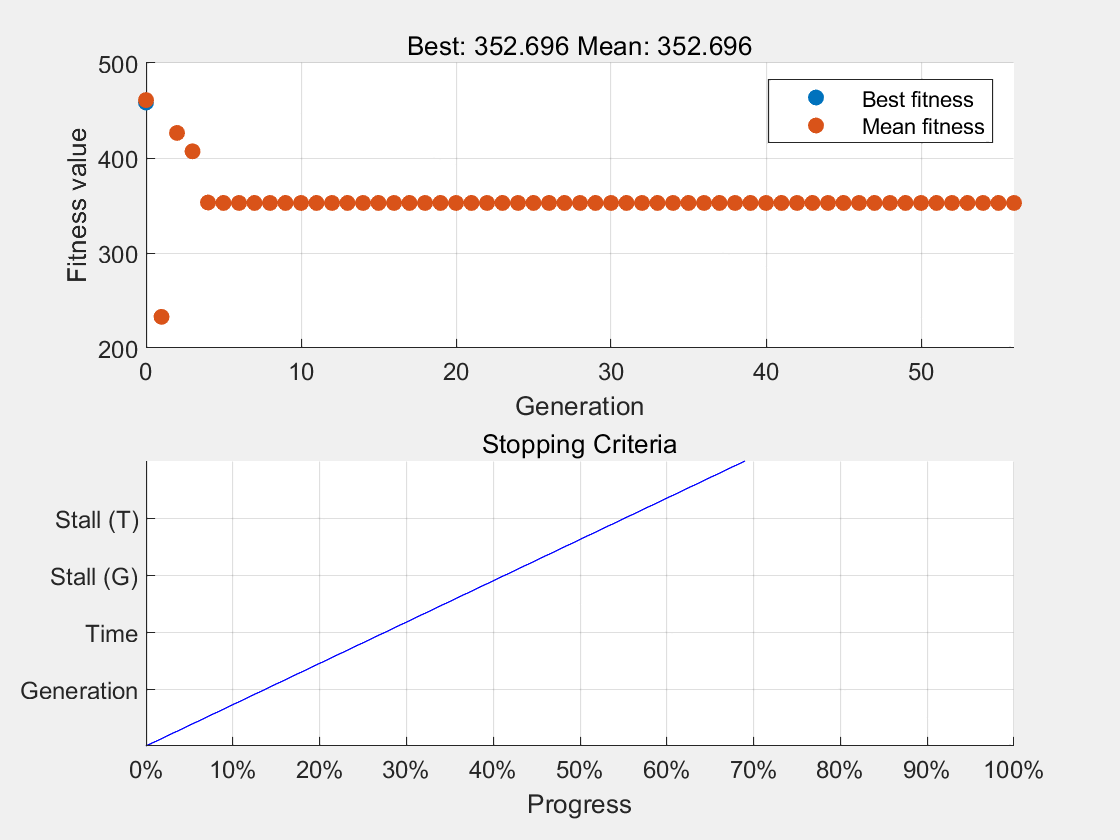

% Convert route to integers and plot the resulting route
route = round(route);
route = [1, route, 1]; % Start and end at the depot
for i = 1:length(route) - 1
    plot([x(route(i)), x(route(i+1))], [y(route(i)), y(route(i+1))], 'b-');
end


disp(['Total Distance: ', num2str(total_dist)]);

Total Distance: 352.696



% 函数定义部分


计算路线route的总距离

function d = calculate_distance(route, dist)
    route = round(route); % 确保路线中的节点是整数
    route = unique(route, 'stable'); % 确保路线中的节点是唯一的，且保持原有顺序
    route = [route, route(1)]; % 将起点（仓库）添加到路线的末尾，确保返回到起点
    n = length(route); % 计算路线中节点的数量
    d = 0; % 初始化总距离为0
    for i = 2:n
        d = d + dist(route(i-1), route(i)); % 逐段累加各节点之间的距离
    end
end

唯一解约束

function [c, ceq] = vrp_constraints(route, n)
    route = round(route);
    c = [];
    ceq = length(unique(route)) - n; % Ensure all cities are visited exactly once
end



